# VBDF2

syms h0 h1 u0 u1 u2
assume([h0,h1], 'positive');
phi = h1/(h1 + h0);
bd = (1+phi) * (u2-u1)/h1 - phi*(u1-u0)/h0;



## linear test


syms lambda R z
u1v = u0 * exp(h0 * lambda);
% u1v = u0 .^(0.5) + u2.^(1-0.5);
u2v = solve(subs(bd,u1,u1v)-lambda*u2,u2);
u2v = simplify(expand(subs(u2v,[h1], h0 * R)));
u2v = simplify(expand(subs(u2v, lambda*h0, z)))

$$u2v = \frac{u_{0}\,\left({\mathrm{e}}^{z}+2\,R\,{\mathrm{e}}^{z}-R^{2}+R^{2}\,{\mathrm{e}}^{z}\right)}{2\,R-R\,z-R^{2}\,z+1}$$


fK = matlabFunction(symfun(u2v/u0,[z,R]));


## Num see

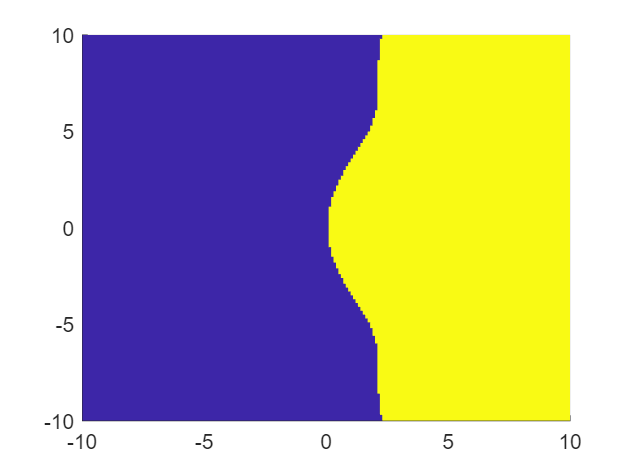

seeRang = 10;
nSee = 201;
reals = linspace(-seeRang,seeRang,nSee);
imags = linspace(-seeRang,seeRang,nSee);
[realm, imagm] = meshgrid(reals,imags);
zsamp = realm + 1i * imagm;
Ksamp = fK(zsamp,10000);
surf(realm,imagm, double(abs(Ksamp)>1), "LineStyle","none");
view([0,90]);